# Matrix Approximation

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code loads the image used in the activity

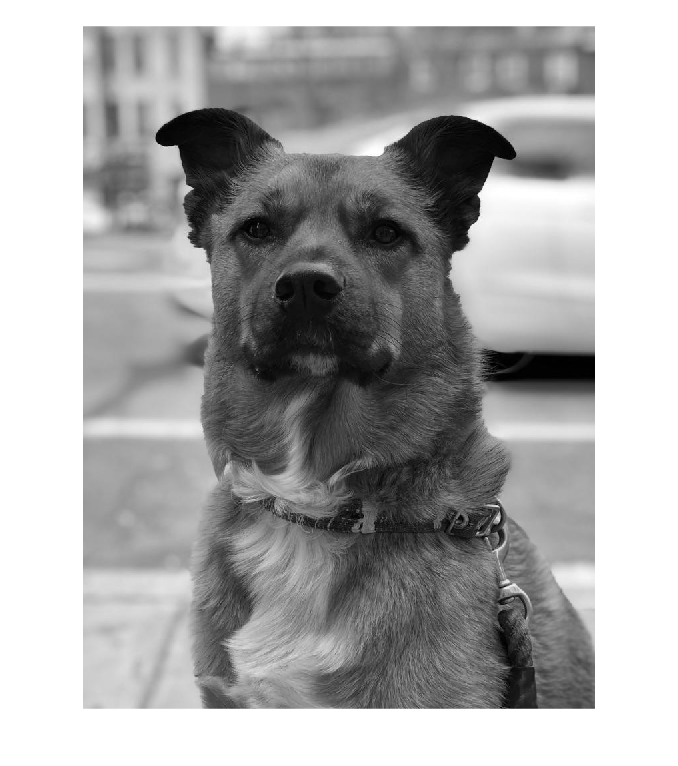

I = im2double(imread("./data/dog.jpg"));
imshow(I)

## Task 1

An image of a dog has been stored in your workspace. 

[U, S, V] = svd(I, "econ")

U =    -0.0376    0.0417   -0.0096    0.0637   -0.0451   -0.0255    0.0232   -0.0368    0.0403   -0.0072    0.0576    0.0201    0.0190    0.0186   -0.0587   -0.0168    0.0184   -0.0407    0.0158   -0.0200   -0.0477    0.0228   -0.0168    0.0333   -0.0123    0.0215    0.0317   -0.0026   -0.0854    0.0450   -0.0359   -0.0010   -0.0123   -0.0332   -0.0760   -0.0289   -0.0421    0.0241   -0.0554    0.0350    0.0194    0.0664   -0.0007    0.0183   -0.0123   -0.0104    0.0099   -0.0014    0.0365    0.0512
   -0.0376    0.0415   -0.0099    0.0638   -0.0456   -0.0252    0.0230   -0.0367    0.0402   -0.0073    0.0576    0.0186    0.0187    0.0188   -0.0577   -0.0157    0.0178   -0.0415    0.0150   -0.0199   -0.0471    0.0220   -0.0172    0.0335   -0.0120    0.0224    0.0320   -0.0028   -0.0836    0.0425   -0.0349   -0.0027   -0.0099   -0.0310   -0.0750   -0.0258   -0.0408    0.0223   -0.0541    0.0346    0.0197    0.0652   -0.0022    0.0191   -0.0141   -0.0104    0.0102   -0.0005    0.0350    0

S =   459.1245         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   94.8423         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.0485    0.0109    0.0095   -0.0343    0.0383    0.0298    0.0183   -0.0555    0.0230   -0.0139    0.0256   -0.0090    0.0585   -0.0053    0.0167   -0.0009   -0.0154    0.0131   -0.0555   -0.0337    0.0213   -0.0115    0.0170   -0.0591    0.0479   -0.0243    0.0083   -0.0418    0.0677   -0.0054    0.0436   -0.0085    0.0003    0.0247    0.0184   -0.0266    0.0518    0.0238    0.0043   -0.0057   -0.0235   -0.0140    0.0272    0.0103   -0.0297    0.0349   -0.0280    0.0204   -0.0138    0.0013
   -0.0485    0.0109    0.0091   -0.0337    0.0387    0.0296    0.0181   -0.0552    0.0234   -0.0128    0.0247   -0.0094    0.0576   -0.0066    0.0165   -0.0011   -0.0142    0.0127   -0.0548   -0.0332    0.0222   -0.0117    0.0167   -0.0584    0.0466   -0.0231    0.0067   -0.0404    0.0685   -0.0059    0.0437   -0.0087    0.0013    0.0241    0.0179   -0.0255    0.0518    0.0230    0.0056   -0.0054   -0.0222   -0.0145    0.0254    0.0088   -0.0276    0.0351   -0.0270    0.0199   -0.0128    0

## Task 2

You can approximate the original matrix using the first `N` singular values using:

`xApprox` `=` `U``(``:,``1``:``N``)``*``S``(``1``:``N``,``1``:``N``)``*``V``(``:,``1``:``N``)``'`

N = 5

N = 5

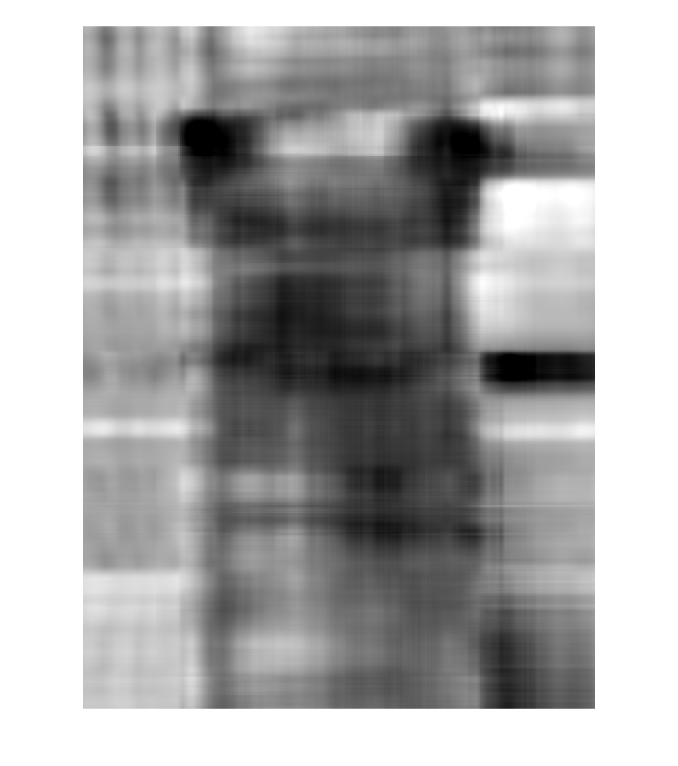

iR = U(:, 1:N)*S(1:N, 1:N)*V(:, 1:N)';
imshow(iR)

## Task 3

The more singular values you use in the approximation, the closer you'll get to the original image. But just how many singular values do you need to use?

There are many different rules-of-thumb to figure this out. One involves plotting the singular values and looking for the "elbow" in the data, or where the singular values start to level off.

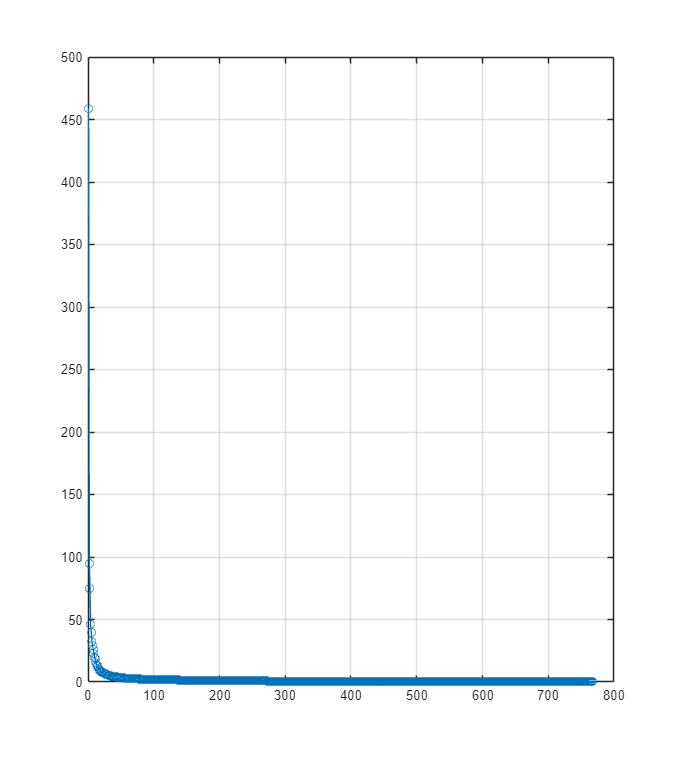

plot(diag(S), "o-")
grid on

## Task 4

Try to zoom in on the "elbow" region by clicking on the plot and selecting  Zoom In.

The singular values seem to start leveling off around the 10th singular value, but finding the "elbow" in the plot is subjective. You could alternatively keep only the number of singular values that capture 95% of the information in the original image.

You can calculate the amount of variance explained by each singular value by calculating the ratio between the *cumulative* sum of the singular values and the sum of the singular values.

`varianceExplained` `=` `100``*``cumsum``(``sv``)``/``sum``(``sv``)`

y = 100*cumsum(diag(S))/sum(diag(S));

## Task 5

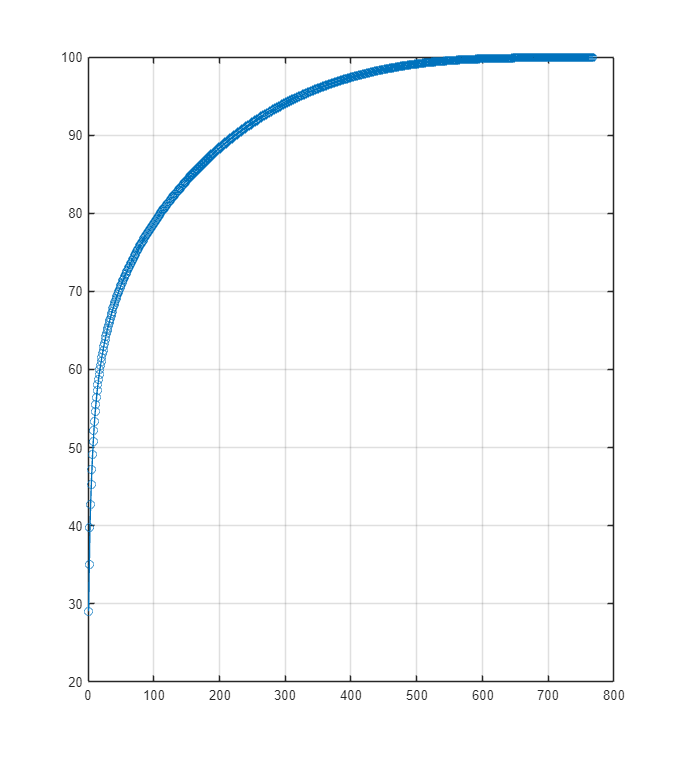

plot(y, "o-")
grid on